clear figure
clear all
Ka = 0.87;
rho = 0.5490

rho = 0.5490

q = 0.5*rho*139.32^2;
WS = 3675

WS = 3675

C_l_des = (1/q) * (WS)

C_l_des = 0.6897

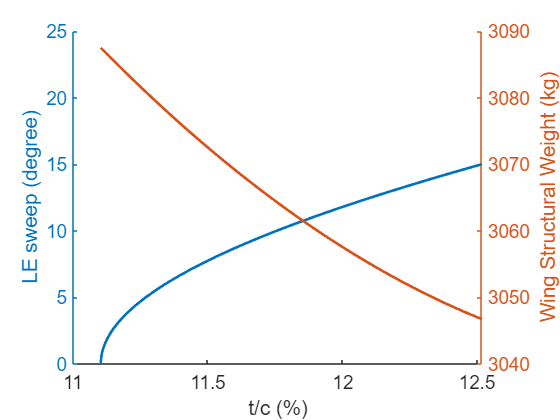

Cldesign = 0.6897;
Mcrit = 0.69;
Mdd = Mcrit;

sweep = 0:0.1:15;
t_c = ((cosd(sweep)).^2).*(Ka./cosd(sweep)-Cldesign./(10*(cosd(sweep)).^3)-Mdd);

yyaxis left
hold on
plot(abs(t_c*100),sweep,'LineWidth',2)
ylim([0 25])
xlabel('t/c (%)')
ylabel('LE sweep (degree)')
set(gca,'fontsize', 14) 
W_dg = convmass(36678,'kg','lbm');
N_z = 1.5*3; % ultimate load factor
S_w = convlength(convlength(85.09591,'m','ft'),'m','ft');
A = 8.5;
% tc_root = 0.12;
lambda = 0.45;
% clear sweep t_c
% syms sweepSolve t_c
% sweep = [0:0.1:20];
% t_c = ((cosd(sweep)).^2).*(Ka./cosd(sweep)-Cldesign./(10*(cosd(sweep)).^3)-Mdd);
% sweep = solve(((cosd(sweepSolve))^2)*(Ka/cosd(sweepSolve)-Cldesign/(10*(cosd(sweepSolve))^3)-Mdd)==t_c, sweepSolve);
S_csw = convlength(convlength(12.5*2,'m','ft'),'m','ft');

W_wing = 0.0051*((W_dg*N_z)^0.557)*(S_w^0.649)*(A^0.5)*(t_c.^(-0.4))*((1+lambda)^0.1).*((cosd(sweep)).^(-1.0))*(S_csw^0.1);
W_wing_inkg = convmass(W_wing,'lbm','kg');
yyaxis right
% [Ax,line1,line2] = plotyy(t_c*100,sweep,t_c*100,W_wing_inkg);
plot(abs(t_c*100),W_wing_inkg,'LineWidth',2);
% set(line2,'LineStyle','--');
% set(line1,'color','black');
% set(line2,'color','black');
%xlim([13.5 17])
% set(Ax(1),'YLim',[0 25])
% xlabel('t/c (%)')
% ylabel(Ax(1),'LE sweep (degree)')
ylabel('Wing Structural Weight (kg)')
hold off

%hold off
% set(Ax,{'ycolor'},{[0 0 0];[0 0 0]})